# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 13-Oct-2021 10:16:27

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["VarName1", "VarName2"], "ThousandsSeparator", ",");

% Import the data
signaldata1 = readtable("C:\Users\Mike Croucher\Desktop\Sheffield_Lunch\signaldata.csv", opts);

## Convert to output type

signaldata1 = table2array(signaldata1)

signaldata1 =     1.0000    0.2688
    2.0000    0.9169
    3.0000   -1.1294
    4.0000    0.4311
    5.0000    0.1594
    6.0000   -0.6538
    7.0000   -0.2168
    8.0000    0.1713
    9.0000    1.7892
   10.0000    1.3847


X = signaldata(:,1);
Y = signaldata(:,2);

## Clear temporary variables

clear opts

## Plot Data

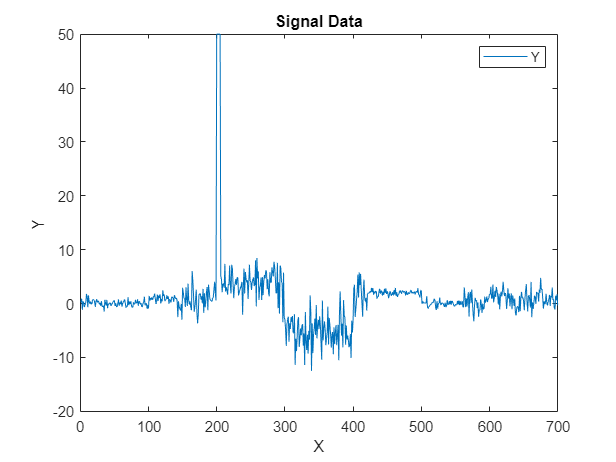

% Create plot of X and Y
h2 = plot(X,Y,'DisplayName','Y');
% Add xlabel, ylabel, title, and legend
xlabel('X')
ylabel('Y')
title('Signal Data')
legend

## Outlier detection and analysis

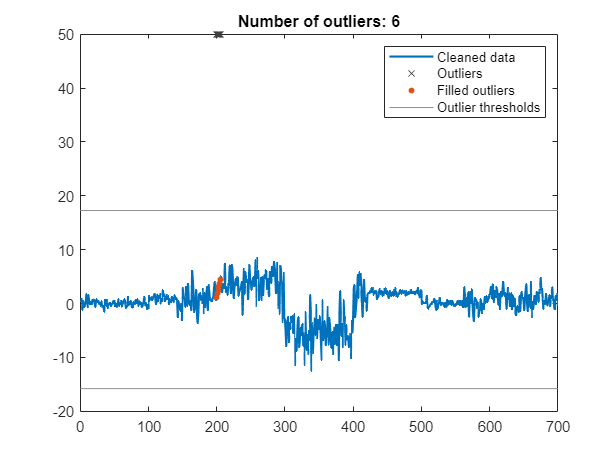

% Fill outliers
[cleanedData2,outlierIndices2,thresholdLow,thresholdHigh] = filloutliers(Y,...
    "linear","mean");

% Display results
clf
plot(cleanedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot outliers
plot(find(outlierIndices2),Y(outlierIndices2),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices2))

% Plot filled outliers
plot(find(outlierIndices2),cleanedData2(outlierIndices2),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend

clear outlierIndices2 thresholdLow thresholdHigh

### Peform changepoint analysis

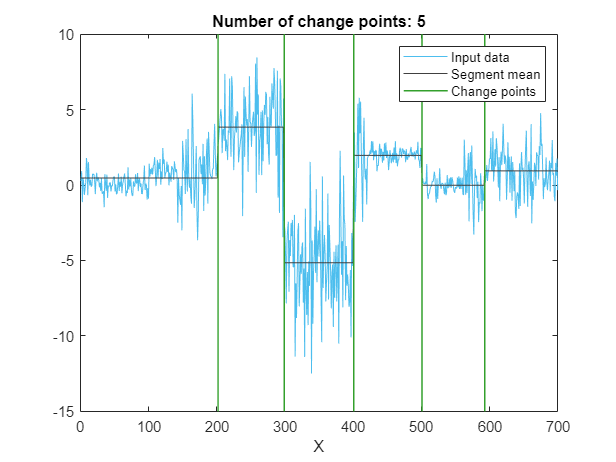

% Find change points
[changeIndices,segmentMean] = ischange(cleanedData,"MaxNumChanges",5,...
    "SamplePoints",X);

% Display results
clf
plot(X,cleanedData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot segments between change points
plot(X,segmentMean,"Color",[64 64 64]/255,"DisplayName","Segment mean")

% Plot change points
x2 = repelem(X(changeIndices),3);
y2 = repmat([ylim(gca) missing]',nnz(changeIndices),1);
plot(x2,y2,"Color",[51 160 44]/255,"LineWidth",1,"DisplayName","Change points")
title("Number of change points: " + nnz(changeIndices))

hold off
legend
xlabel("X")

clear segmentMean x2 y2